# BUCK CONVERTER — Modello matematico completo

### **PARTE 1 :**

**Riferimento**: *Lena, Setti, Pareschi* 

## Setup iniziale

clear; close all; clc;

fprintf('=================================================================\n');

fprintf(' BUCK CONVERTER — Modello matematico completo\n');

 BUCK CONVERTER — Modello matematico completo


fprintf(' Ref: Lena, Setti, Pareschi et al., arXiv:2509.02102v1\n');

 Ref: Lena, Setti, Pareschi et al., arXiv:2509.02102v1


fprintf('=================================================================\n\n');

## Sezione 1.1 — Parametri nominali 

In questa sezione definiamo i componenti fisici del power stage, i parametri di sistema e le incertezze relative associate a ciascun componente.

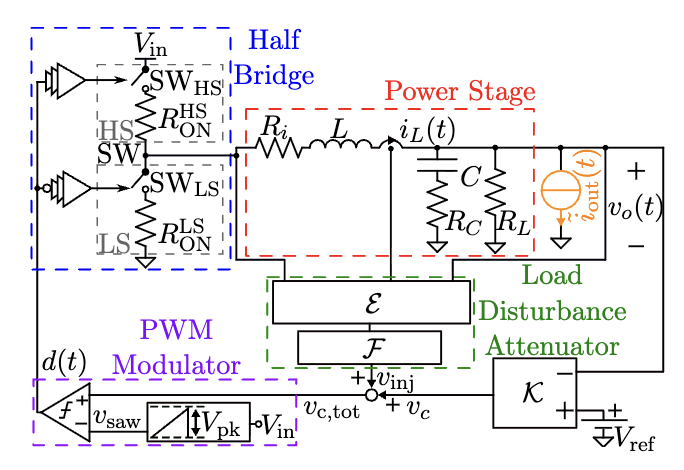

fprintf('--- SEZIONE 1: Parametri nominali (Tabella 1) ---\n');

--- SEZIONE 1: Parametri nominali (Tabella 1) ---



% --- Componenti del Power Stage ---
C     = 0.249e-3;   % [F]    Condensatore di uscita 
L     = 8.2e-6;     % [H]    Induttore 
R_c   = 0.115e-3;   % [Ohm]  ESR condensatore 
R_i   = 7e-3;       % [Ohm]  Resistenza avvolgimento induttore 
R_ON  = 6.5e-3;     % [Ohm]  R_ON^{HS,LS} MOSFET 

% --- Parametri di sistema ---
f_sw      = 500e3;      % [Hz]     Frequenza di switching
omega_sw  = 2*pi*f_sw;  % [rad/s]
k_FF      = 30;         % [-]      Costante feedforward PWM
V_target  = 5.0;        % [V]      Tensione di uscita target
I_max     = 10.0;       % [A]      Corrente massima di uscita
V_in_max  = 20.0;       % [V]      Tensione massima di ingresso

% --- Incertezze relative (per uso futuro in mu-analysis) ---
delta_C   = 0.10;  % +10%
delta_L   = 0.20;  % +20%
delta_Rc  = 0.15;  % +15%
delta_Ri  = 0.15;  % ±15%
delta_RON = 0.15;  % ±15%

fprintf('  C     = %.4f mF\n',   C*1e3);

  C     = 0.2490 mF


fprintf('  L     = %.2f uH\n',   L*1e6);

  L     = 8.20 uH


fprintf('  R_c   = %.4f mOhm (ESR condensatore)\n',        R_c*1e3);

  R_c   = 0.1150 mOhm (ESR condensatore)


fprintf('  R_i   = %.2f mOhm (resistenza avvolgimento)\n', R_i*1e3);

  R_i   = 7.00 mOhm (resistenza avvolgimento)


fprintf('  R_ON  = %.2f mOhm (MOSFET ON resistance)\n',    R_ON*1e3);

  R_ON  = 6.50 mOhm (MOSFET ON resistance)


fprintf('  f_sw  = %.0f kHz\n', f_sw/1e3);

  f_sw  = 500 kHz


fprintf('  k_FF  = %d\n',       k_FF);

  k_FF  = 30


fprintf('  V_target = %.1f V\n', V_target);

  V_target = 5.0 V


fprintf('\n'); 

## Sezione 1.2 — Intervallo di carico R_L (eq. 1)

Garantisce il funzionamento in CCM (Continuous Conduction Mode).


$$R_{L,min} = \frac{V_{target}}{I_{max}}$$



$$R_{L,max} = \frac{2 * L_{min} f_{sw}}{1 - \frac{V_{target}}{V_{in,max}}}$$


fprintf('--- SEZIONE 1.2: Intervallo di carico R_L (eq. 1) ---\n');

--- SEZIONE 1.2: Intervallo di carico R_L (eq. 1) ---



L_min   = L * (1 - delta_L);       % L con incertezza massima negativa
R_L_min = V_target / I_max;        % Limite inferiore (corrente massima)
R_L_max = (2 * L_min * f_sw) / ...
    (1 - V_target / V_in_max); % Limite superiore (garantisce CCM)

% Valore nominale: media geometrica dell'intervallo
R_L = sqrt(R_L_min * R_L_max);

fprintf('  L_min    = %.4f uH (L con incertezza -20%%)\n', L_min*1e6);

  L_min    = 6.5600 uH (L con incertezza -20%)


fprintf('  R_L_min  = V_target/I_max = %.4f Ohm\n', R_L_min);

  R_L_min  = V_target/I_max = 0.5000 Ohm


fprintf('  R_L_max  = 2*L_min*f_sw/(1-V_target/V_in_max) = %.4f Ohm\n', R_L_max);

  R_L_max  = 2*L_min*f_sw/(1-V_target/V_in_max) = 8.7467 Ohm


fprintf('  R_L nom  = sqrt(R_L_min * R_L_max) = %.4f Ohm\n', R_L);

  R_L nom  = sqrt(R_L_min * R_L_max) = 2.0913 Ohm


fprintf('  Intervallo I_R_L = [%.4f, %.4f] Ohm\n', R_L_min, R_L_max);

  Intervallo I_R_L = [0.5000, 8.7467] Ohm


fprintf('\n');

## Sezione 1.3 — Parametri derivati (eq. 13)

Resistenza equivalente : 


$$R'_i = R_i + R_{ON}^{HS,LS}$$



$$R'_c = R_L + R_c$$


Coefficienti del denominatore comune $D(s) = a_0 s^2 + a_1 s + a_2$:


$$a_0 = C \, L \, (R_L + R_c)$$



$$a_1 = L + C R_L (R_C + R'_i) + C R_C R'_i$$


 
$$a_2 =R_L +R\prime_i$$


fprintf('--- SEZIONE 1.3: Parametri derivati e coefficienti (eq. 13) ---\n');

--- SEZIONE 1.3: Parametri derivati e coefficienti (eq. 13) ---



% Resistenze equivalenti
R_i_prime = R_i + R_ON;   % R'_i = R_i + R_ON [Ohm]
R_c_prime = R_L + R_c;    % R'_c = R_L + R_c [Ohm]

% Coefficienti denominatore comune D(s)
a0 = C * L * (R_L + R_c);
a1 = (L + C*R_L*(R_c + R_i_prime) + C*R_c*R_i_prime);
a2 = R_L + R_i_prime ;

fprintf('  R_i_prime = R_i + R_ON = %.4f mOhm\n', R_i_prime*1e3);

  R_i_prime = R_i + R_ON = 13.5000 mOhm


fprintf('  R_c_prime = R_L + R_c = %.6f Ohm\n', R_c_prime);

  R_c_prime = R_L + R_c = 2.091367 Ohm


fprintf('\n');
fprintf('  Coefficienti denominatore D(s) = a0*s^2 + a1*s + a2:\n');

  Coefficienti denominatore D(s) = a0*s^2 + a1*s + a2:


fprintf('  a0 = C*L*(R_L+R_c) = %.6e\n', a0);

  a0 = C*L*(R_L+R_c) = 4.270152e-09


fprintf('  a1 = L + C*R_c*(R_L+R_i'') + C*R_L*R_i'' = %.6e\n', a1);

  a1 = L + C*R_c*(R_L+R_i') + C*R_L*R_i' = 1.529001e-05


fprintf('  a2 = R_L + R_i'' + R_c = %.6f Ohm\n', a2);

  a2 = R_L + R_i' + R_c = 2.104752 Ohm


fprintf('\n');

% Denominatore comune come polinomio [a0, a1, a2]
den = [a0, a1, a2];

## Sezione 2 — Modello lineare PWM + Half Bridge (eq. 9-10)

Modello nonlineare :


$$\[
d(t)=
\begin{cases}
0, & \text{se } v_c(t) < v_{saw}(t),\\
1, & \text{altrimenti.}
\end{cases}
\]$$


Sotto Assunzioni 1-2 (piccolo segnale, banda < f_sw), con feedforward    

                                      $V_{pk} = \frac{V_{in}}{k_{FF}}$ (eq. 10):


$$v_{SW}(t) = k_{FF} \, v_c(t) + d_a(t)$$


Guadagno PWM (costante, indipendente da $V_{in}$):


$$G_{PWM} = k_{FF} = 30$$


fprintf('--- SEZIONE 2: Modello lineare PWM + Half Bridge ---\n');

--- SEZIONE 2: Modello lineare PWM + Half Bridge ---



G_PWM = k_FF;   % Guadagno PWM con feedforward 

% Come tf MATLAB: guadagno puro
PWM_tf = tf(G_PWM, 1);

fprintf('  Guadagno PWM con feedforward:\n');

  Guadagno PWM con feedforward:


fprintf('  G_PWM = k_FF = %d (indipendente da V_in)\n', G_PWM);

  G_PWM = k_FF = 30 (indipendente da V_in)


fprintf('  Modello: v_SW(s) = k_FF * v_c(s) = %d * v_c(s)\n', k_FF);

  Modello: v_SW(s) = k_FF * v_c(s) = 30 * v_c(s)


fprintf('\n');

## Sezione 2.1 — Power Stage: matrice P(s) (eq. 11-12)


$$\left[
\matrix{
v_o(s) \cr
i_L(s)
}
\right]
=
\left[
\matrix{
P_{11}(s) & P_{12}(s) \cr
P_{21}(s) & P_{22}(s)
}
\right]
\left[
\matrix{
v_{SW}(s) \cr
\hat{i}_{out}(s)
}
\right]$$



$$P_{11}(s)=\frac{R_L\left(1+C R_c s\right)}{D(s)}
=
P_{22}(s)
\qquad
(\mathrm{eq.\ 12a})$$



$$P_{12}(s)=
\frac{R_L\left[-C L R_c s^2-\left(L+C R_c R'_i\right)s-R'_i\right]}
{D(s)}
\qquad
(\mathrm{eq.\ 12b})$$



$$P_{21}(s)=
\frac{C\left(R_L+R_c\right)s+1}
{D(s)}
\qquad
(\mathrm{eq.\ 12c})$$


fprintf('--- SEZIONE 2.1: Power Stage P(s) ---\n');

--- SEZIONE 2.1: Power Stage P(s) ---



num_P11 = R_L * [C*R_c, 1];
P11 = tf(num_P11, den);
P22 = P11;   % P11 = P22

fprintf('  P11(s) = P22(s) = v_o(s)/v_SW(s):\n');

  P11(s) = P22(s) = v_o(s)/v_SW(s):


fprintf('  Num = R_L*(C*R_c*s + 1) = [%.4e, %.4f]\n', num_P11(1), num_P11(2));

  Num = R_L*(C*R_c*s + 1) = [5.9883e-08, 2.0913]


fprintf('  DC gain P11(0) = R_L/a2 = %.6f\n', R_L/a2);

  DC gain P11(0) = R_L/a2 = 0.993586



z_ESR = -1/(C*R_c);
f_ESR = abs(z_ESR)/(2*pi);
fprintf('  Zero ESR: z1 = -1/(C*R_c) = %.4e rad/s => f = %.2f kHz\n', ...
    z_ESR, f_ESR/1e3);

  Zero ESR: z1 = -1/(C*R_c) = -3.4922e+07 rad/s => f = 5558.06 kHz


fprintf('\n');


num_P12 = R_L * [-C*L*R_c, -(L + C*R_c*R_i_prime), -R_i_prime];
P12 = tf(num_P12, den);

fprintf('  P12(s) = v_o(s)/i_out_hat(s) [impedenza uscita]:\n');

  P12(s) = v_o(s)/i_out_hat(s) [impedenza uscita]:


fprintf('  Num = R_L*[-C*L*R_c*s^2 - (L+C*R_c*R_ip)*s - R_ip]\n');

  Num = R_L*[-C*L*R_c*s^2 - (L+C*R_c*R_ip)*s - R_ip]


fprintf('      = [%.4e, %.4e, %.6f]\n', num_P12(1), num_P12(2), num_P12(3));

      = [-4.9104e-13, -1.7149e-05, -0.028232]


fprintf('  DC gain P12(0) = -R_L*R_ip/a2 = %.6f Ohm\n', -R_L*R_i_prime/a2);

  DC gain P12(0) = -R_L*R_ip/a2 = -0.013413 Ohm


fprintf('\n');


num_P21 = [C*(R_L + R_c), 1];
P21 = tf(num_P21, den);

fprintf('  P21(s) = i_L(s)/v_SW(s):\n');

  P21(s) = i_L(s)/v_SW(s):


fprintf('  Num = C*(R_L+R_c)*s + 1 = [%.4e, 1]\n', num_P21(1));

  Num = C*(R_L+R_c)*s + 1 = [5.2075e-04, 1]


fprintf('  DC gain P21(0) = 1/a2 = %.4f A/V\n', 1/a2);

  DC gain P21(0) = 1/a2 = 0.4751 A/V


fprintf('\n');

## Sezione 2.2 — FdT open-loop G(s) = k_FF * P11(s) (eq. 14)


$$G^{v_o}_{v_c}(s) = \frac{v_o(s)}{v_c(s)} = k_{FF} \, P_{11}(s)$$


Questa è la FdT di piccolo segnale dell'intera pianta (PWM + HB + PS) usata come base per il progetto di K.

fprintf('--- SEZIONE 2.2: FdT open-loop G(s) = k_FF * P11(s) (eq. 14) ---\n');

--- SEZIONE 2.2: FdT open-loop G(s) = k_FF * P11(s) (eq. 14) ---



G = G_PWM * P11;   % G(s) = k_FF * P11(s)
G1 = minreal(G);
% Coefficienti espliciti
num_G = k_FF * num_P11;   % [k_FF*R_L*C*R_c, k_FF*R_L]

fprintf('  G(s) = k_FF * P11(s):\n');

  G(s) = k_FF * P11(s):


fprintf('  Num = [%.4e, %.4f]\n', num_G(1), num_G(2));

  Num = [1.7965e-06, 62.7375]


fprintf('  Den = [%.4e, %.4e, %.4f]\n', den(1), den(2), den(3));

  Den = [4.2702e-09, 1.5290e-05, 2.1048]


fprintf('\n');

% Proprietà
DC_gain_G = dcgain(G);
fprintf('  Proprieta'' di G(s):\n');

  Proprieta' di G(s):


fprintf('  Guadagno DC G(0) = k_FF * R_L/a2 = %.4f\n', DC_gain_G);

  Guadagno DC G(0) = k_FF * R_L/a2 = 29.8076


fprintf('  Zero ESR: f_ESR = %.2f kHz (fuori banda, trascurabile)\n', f_ESR/1e3);

  Zero ESR: f_ESR = 5558.06 kHz (fuori banda, trascurabile)


fprintf('\n');

% Poli di G(s) = poli di P11(s) = radici del denominatore
poli_G = pole(G);
fprintf('  Poli di G(s):\n');

  Poli di G(s):


for k = 1:length(poli_G)
    if imag(poli_G(k)) ~= 0
        fprintf('    p%d = %.4f + j*%.4f rad/s\n', k, real(poli_G(k)), imag(poli_G(k)));
    else
        fprintf('    p%d = %.4f rad/s\n', k, real(poli_G(k)));
    end
end

    p1 = -1790.3356 + j*22129.0122 rad/s
    p2 = -1790.3356 + j*-22129.0122 rad/s



% Frequenze caratteristiche del Power Stage
omega_PS = sqrt(a2/a0);          % pulsazione naturale [rad/s]
f_PS     = omega_PS/(2*pi);      % frequenza naturale [Hz]
zeta_PS  = (a1/(2*sqrt(a0*a2)));   % smorzamento

fprintf('\n  Frequenze caratteristiche del Power Stage:\n');


  Frequenze caratteristiche del Power Stage:


fprintf('  omega_PS = sqrt(a2/a0) = %.4f rad/s\n', omega_PS);

  omega_PS = sqrt(a2/a0) = 22201.3171 rad/s


fprintf('  f_PS = omega_PS/(2*pi) = %.4f Hz (~%.2f kHz)\n', f_PS, f_PS/1e3);

  f_PS = omega_PS/(2*pi) = 3533.4494 Hz (~3.53 kHz)


fprintf('  zeta_PS = a1/(2*sqrt(a0*a2)) = %.6f\n', zeta_PS);

  zeta_PS = a1/(2*sqrt(a0*a2)) = 0.080641


fprintf('  omega_ESR = 1/(C*R_c) = %.4e rad/s => f_ESR = %.2f kHz\n', ...
    abs(z_ESR), f_ESR/1e3);

  omega_ESR = 1/(C*R_c) = 3.4922e+07 rad/s => f_ESR = 5558.06 kHz


fprintf('\n');

%per visualizzare la funzione di trasferimento
zpk(G1)


ans =
 
    420.71 (s+3.492e07)
  ------------------------
  (s^2 + 3581s + 4.929e08)
 
Continuous-time zero/pole/gain model.


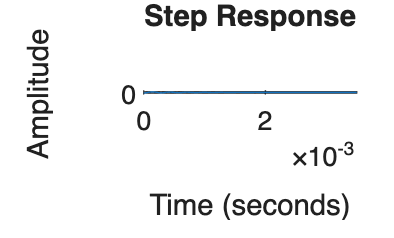

figure;
%Risposta al gradino della funzione di trasferimento
step(G1);



%Gjw = squeeze(freqresp(G, omega_PS));
%[Y, S, U] = svd(Gjw);
%sigma_max = S(1,1);  
%figure;
%sigma(G)
%sigma_max_dB = 20*log10(sigma_max);
%fprintf('SVD max: %.4f\n', sigma_max)          
%fprintf('SVD max in dB: %.4f\n', sigma_max_dB) 
%norm(G, 'Inf')



## Sezione 2.3— Vettore di frequenze per i grafici di Bode

Vettore di frequenze usato per i diagrammi di Bode/sigma, da 10 Hz fino a 5 volte la frequenza di switching.

f_vec = logspace(1, log10(5*f_sw), 2000);
omega_vec = 2*pi*f_vec;

## Sezione 2.4— Famiglia incerta: ureal 

**Passo 1: costruzione della famiglia di impianti **$G_i (s)$

Per ogni combinazione degli estremi dei parametri incerti $\left(L,C,R_i ,R_c ,R_{\mathrm{ON}} \right)\;$si calcola una realizzazione di G(s). 

**Passo 2: modello incerto con ureal**

Si definisce $G_{\textrm{unc}} \left(s\right)$ come sistema con parametri ureal — oggetto nativo del Robust Control Toolbox di MATLAB che rappresenta l'incertezza strutturata parametrica.

fprintf('--- SEZIONE 2.4: Famiglia incerta e ucover ---\n');

--- SEZIONE 2.4: Famiglia incerta e ucover ---



% --- PASSO 1: Campionamento del polytope di incertezza ---
% Estremi di ogni parametro (±incertezza nominale)
L_vals   = [L*(1-delta_L),   L*(1+delta_L)  ];   % [L_min, L_max]
C_vals   = [C*(1-delta_C),   C*(1+delta_C)  ];
Ri_vals  = [R_i*(1-delta_Ri), R_i*(1+delta_Ri)];
Rc_vals  = [R_c*(1-delta_Rc), R_c*(1+delta_Rc)];
RON_vals = [R_ON*(1-delta_RON),R_ON*(1+delta_RON)];

% Funzione locale: calcola G(s) per dati parametri
function Gk = build_G(Lk, Ck, Rik, Rck, RONk, R_L, k_FF)
    Ripk = Rik + RONk;
    a0k  = Ck*Lk*(R_L + Rck);
    a1k  = Lk + Ck*R_L*(Rck+Ripk) + Ck*Rck*Ripk;
    a2k  = R_L + Ripk;
    num  = k_FF * R_L * [Ck*Rck, 1];
    den  = [a0k, a1k, a2k];
    Gk   = tf(num, den);
end

% Vertici del polytope (2^5 = 32 combinazioni)
params = {L_vals, C_vals, Ri_vals, Rc_vals, RON_vals};
n_params = numel(params);
n_vert   = 2^n_params;   % 32 vertici
G_array  = cell(n_vert, 1);

for idx = 1:n_vert
    bits = dec2bin(idx-1, n_params) - '0';   % vettore binario [0/1]
    Lk   = params{1}(bits(1)+1);
    Ck   = params{2}(bits(2)+1);
    Rik  = params{3}(bits(3)+1);
    Rck  = params{4}(bits(4)+1);
    RONk = params{5}(bits(5)+1);
    G_array{idx} = build_G(Lk, Ck, Rik, Rck, RONk, R_L, k_FF);
end

% Stack come array di FdT
G_stack = stack(1, G_array{:});
G0      = G;   % impianto nominale

fprintf('  Famiglia generata: %d vertici del polytope di incertezza\n', n_vert);

  Famiglia generata: 32 vertici del polytope di incertezza


fprintf('  Parametri variati: L(±%.0f%%), C(±%.0f%%), Ri(±%.0f%%), Rc(±%.0f%%), RON(±%.0f%%)\n', ...
        delta_L*100, delta_C*100, delta_Ri*100, delta_Rc*100, delta_RON*100);

  Parametri variati: L(±20%), C(±10%), Ri(±15%), Rc(±15%), RON(±15%)


% --- PASSO 2: Sistema incerto con ureal in SPAZIO DI STATO (Ottimizzato per M11) ---

% I tuoi parametri ureal originali
L_u   = ureal('L_u',   L,   'Range', L_vals);
C_u   = ureal('C_u',   C,   'Range', C_vals);
Ri_u  = ureal('Ri_u',  R_i, 'Range', Ri_vals);
Rc_u  = ureal('Rc_u',  R_c, 'Range', Rc_vals);
RON_u = ureal('RON_u', R_ON,'Range', RON_vals);

% Invece di far calcolare a MATLAB 1/L_u direttamente nelle matrici, 
% definiamo l'inverso mediante la relazione algebrica ben condizionata:
Rip_u  = Ri_u + RON_u;
R_eq_u = R_L / (R_L + Rc_u);

% Inversi espliciti per la matrice di stato
invL_u = 1 / L_u;
invC_u = 1 / C_u;

% Assemblaggio delle matrici di stato in forma esplicita
A_u = [ -(Rip_u + Rc_u*R_eq_u) * invL_u,  -R_eq_u * invL_u ;
    R_eq_u * invC_u,                 -invC_u / (R_L + Rc_u) ];

B_u = [ k_FF * invL_u ; 
    0 ];

C_u_mat = [ Rc_u * R_eq_u,  R_eq_u ];
D_u     = 0;

% Creazione del modello State-Space incerto
G_unc_ss = ss(A_u, B_u, C_u_mat, D_u);

% Riduzione dell'ordine LFT (ELIMINA I BLOCCHI RIDONDANTI che gonfiano M11)
G_unc_use = simplify(G_unc_ss, 'Full');
zpk(G_unc_use)


ans =
 
    420.71 (s+3.492e07)
  ------------------------
  (s^2 + 3581s + 4.929e08)
 
Continuous-time zero/pole/gain model.



%%DERIVAZIONE ALGEBRICA PIANTA INCERTA
% Parametri derivati incerti
%Rip_u  = Ri_u + RON_u;
a0_u   = C_u * L_u * (R_L + Rc_u);
a1_u   = L_u + C_u*R_L*(Rc_u+Rip_u) + C_u*Rc_u*Rip_u;
a2_u   = R_L + Rip_u;
s = tf('s');
%P11_u(s) con incertezza strutturata sui 5 parametri fisici
P11_u_use= R_L * (1 + C_u*Rc_u*s) / (a0_u*s^2 + a1_u*s + a2_u);

%Pianta open-loop incerta: G_unc(s) = k_FF * P11_u(s)
G_unc_use1 = k_FF * P11_u_use;
zpk(G_unc_use1)


ans =
 
    420.71 (s+3.492e07)
  ------------------------
  (s^2 + 3581s + 4.929e08)
 
Continuous-time zero/pole/gain model.


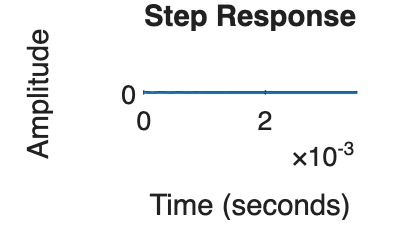


%Risposta al gradino della pianta incerta
figure; step(G_unc_use);

fprintf('  Modello ureal costruito sui 5 parametri incerti\n\n');

  Modello ureal costruito sui 5 parametri incerti




% G(s) incerta: numeratore e denominatore con ureal
%num_u = k_FF * R_L * [Rc_u*C_u, 1];   % vettore simbolico ureal
%Per confrontarla con quella ricavata algebricamente
%G0new = minreal(tf(G_unc_use.nominal)); 
%zpk(G0new);

## Sezione 2.5 — Definizione pesi W1(s) e W2(s) con makeweight

Makeweight(DC, fc, HF) costruisce un peso del primo ordine con:

- guadagno a bassa frequenza (DC) [lin, non dB]

- frequenza di crossover (fc) [rad/s]

- guadagno ad alta frequenza (HF) [lin, non dB]

La forma è: $W(s) = \frac{s/M + w_0}{s + w_0 \varepsilon}$ con $M = DC$, $\varepsilon = HF$, $w_0 = fc$.

**Logica di taratura (coerente con eq. 25 del paper)**

$W_1(s)$ agisce su S: $|S(j\omega)| < \frac{1}{|W_1(j\omega)|}$

$W_2(s)$ agisce su T: $|T(j\omega)| < \frac{1}{|W_2(j\omega)|}$

%% SEZIONE 2.5 — Pesi W1(s), W2(s): makeweight 
fprintf('--- SEZIONE 9: pesi W1, W2 — makeweight vs paper ---\n');

--- SEZIONE 9: pesi W1, W2 — makeweight vs paper ---



% ────────────────────────────────────────────────────────────────────
% Parametri 
% ────────────────────────────────────────────────────────────────────
%Sp0     = 2.5;              
%Tp0     = 4;
%zeta_s  = 0.6;
%zeta_t  = 0.2;
omega_s = 1.3*omega_sw;
omega_t = omega_sw;

eps_int = omega_vec(1) * 1e-3;   % polo quasi-zero, per la regolarizzazione
p_hf_W2 = 50 * omega_sw;         % polo cheap, per rendere W2 propria

% ── W1: versione makeweight ───────────────
% Un solo blocco del prim'ordine: NON puo' replicare la gobba di
% risonanza 
W1_shelf = makeweight(100, omega_sw/15 , 0.65);
W2 = minreal(makeweight(0.05, omega_sw/5, 5));


## Sezione 2.6 — Definizione pesi W1(s) e W2(s) analiticamente

%% SEZIONE 2.6 — Pesi W1(s), W2(s) costruiti analiticamente 
fprintf('--- SEZIONE 9: pesi W1, W2 analitici (eq. 25) ---\n');

--- SEZIONE 9: pesi W1, W2 analitici (eq. 25) ---



Sp0_real    = 4; 
Tp0_real    = 4; 
zeta_s_real  = 0.6;
zeta_t_real  = 0.2;
omega_s_real = 1.1*omega_sw;        % [rad/s]
omega_t_real = omega_sw / 5;       % [rad/s]

% ────────────────────────────────────────────────────────────────────
% W1(s): forma esatta, con polo in s=0 regolarizzato in s=-eps_int
%
%   W1(s) = (s^2 + 2*zeta_s*omega_s*s + omega_s^2)
%           -------------------------------------------
%              Sp0 * s * (s + 2*zeta_s*omega_s)
% ────────────────────────────────────────────────────────────────────
eps_int_real = omega_vec(1) * 1e-3;   % polo "quasi-zero", 3 decadi sotto omega_vec(1)
num_W1 = [1, 2*zeta_s_real*omega_s_real, omega_s_real^2];
den_W1 = Sp0_real * conv([1, eps_int_real], [1, 2*zeta_s_real*omega_s_real]);
W1_real = minreal(tf(num_W1, den_W1));


fprintf('  W1(s): polo in s=0 regolarizzato a s=-%.4e rad/s\n', eps_int_real);

  W1(s): polo in s=0 regolarizzato a s=-6.2832e-02 rad/s


fprintf('  isstable(W1) = %d, isproper(W1) = %d\n', isstable(W1_real), isproper(W1_real));

  isstable(W1) = 1, isproper(W1) = 1




% ────────────────────────────────────────────────────────────────────
% W2(s): forma esatta del paper, IMPROPRIA (grado 2 su grado 0),
% regolarizzata con un polo cheap ad alta frequenza per garantire
% che sia propria
%
%   W2(s) = (s^2 + 2*zeta_t*omega_t*s + omega_t^2)
%           -------------------------------------------
%                       Tp0 * omega_t^2
% ────────────────────────────────────────────────────────────────────
p_hf_W2 = 50 * omega_sw;   % polo cheap, ben oltre omega_sw
den_regolarizzazione = [1/(p_hf_W2^2), 2/p_hf_W2, 1];
num_W2 = [1, 2*zeta_t_real*omega_t_real, omega_t_real^2];
den_W2 = Tp0_real*omega_t_real^2 * den_regolarizzazione;
W2_real = minreal(tf(num_W2, den_W2));

fprintf('  W2(s): regolarizzata con polo cheap a p_hf = %.2e rad/s\n', p_hf_W2);

  W2(s): regolarizzata con polo cheap a p_hf = 1.57e+08 rad/s


fprintf('  isstable(W2) = %d, isproper(W2) = %d\n', isstable(W2_real), isproper(W2_real));

  isstable(W2) = 1, isproper(W2) = 1




fprintf('--- Verifica pesi prima della sintesi H-infinity ---\n');

--- Verifica pesi prima della sintesi H-infinity ---


fprintf('  W1: stabile=%d, proprio=%d\n', isstable(W1_real), isproper(W1_real));

  W1: stabile=1, proprio=1


fprintf('  W2: stabile=%d, proprio=%d\n', isstable(W2_real), isproper(W2_real));

  W2: stabile=1, proprio=1


if ~isstable(W1_real) || ~isstable(W2_real)
    error('Uno dei pesi non e'' stabile: controlla eps_int/p_hf_W2');
end
fprintf('  OK\n\n');

  OK



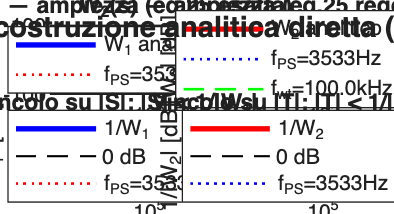


% ────────────────────────────────────────────────────────────────────
% Figura 9: Bode dei pesi 
% ────────────────────────────────────────────────────────────────────
if ~exist('f_col','var');  f_col  = omega_vec/(2*pi); end
if ~exist('f_PS','var');   f_PS   = omega_PS/(2*pi);  end
if ~exist('f_wt','var');   f_wt   = omega_t_real/(2*pi);   end
f_wcW1 = omega_s/(2*pi);   

[mW1,  ~] = bode(W1_real,  omega_vec); mW1  = squeeze(mW1(:));
[mW2,  ~] = bode(W2_real,  omega_vec); mW2  = squeeze(mW2(:));

figure('Name','Pesi W1(s) e W2(s) — formula analitica eq.25','NumberTitle','off', ...
       'Position',[100 100 1100 600]);

subplot(2,2,1);
semilogx(f_col, 20*log10(mW1), 'b', 'LineWidth', 2); hold on;
plot([f_PS f_PS], [-60 100], 'r:', 'LineWidth', 1);
grid on; xlim([f_col(1) f_col(end)]);
xlabel('Frequenza [Hz]'); ylabel('|W_1| [dB]'); title('W_1(s) — ampiezza (eq.25 esatta)');
legend('W_1 analitico', sprintf('f_{PS}=%.0fHz',f_PS), 'Location','best','FontSize',8);

subplot(2,2,2);
semilogx(f_col, 20*log10(mW2), 'r', 'LineWidth', 2); hold on;
plot([f_PS f_PS], [-60 60], 'b:', 'LineWidth', 1);
plot([f_wt f_wt], [-60 60], 'g--','LineWidth', 1);
grid on; xlim([f_col(1) f_col(end)]);
xlabel('Frequenza [Hz]'); ylabel('|W_2| [dB]'); title('W_2(s) — ampiezza (eq.25 regolarizzata)');
legend('W_2 analitico', sprintf('f_{PS}=%.0fHz',f_PS), sprintf('f_{wt}=%.1fkHz',f_wt/1e3), ...
       'Location','best','FontSize',8);

subplot(2,2,3);
semilogx(f_col, -20*log10(mW1), 'b', 'LineWidth', 2); hold on;
plot(get(gca,'XLim'), [0 0], 'k--', 'LineWidth', 0.8);
plot([f_PS f_PS], get(gca,'YLim'), 'r:', 'LineWidth', 1);
grid on; xlim([f_col(1) f_col(end)]); ylim([-40 100]);
xlabel('Frequenza [Hz]'); ylabel('1/|W_1| [dB]'); title('Vincolo su |S|: |S| < 1/|W_1|');
legend('1/W_1','0 dB', sprintf('f_{PS}=%.0fHz',f_PS), 'Location','best','FontSize',8);

subplot(2,2,4);
semilogx(f_col, -20*log10(mW2), 'r', 'LineWidth', 2); hold on;
plot(get(gca,'XLim'), [0 0], 'k--', 'LineWidth', 0.8);
plot([f_PS f_PS], get(gca,'YLim'), 'b:', 'LineWidth', 1);
grid on; xlim([f_col(1) f_col(end)]); ylim([-40 30]);
xlabel('Frequenza [Hz]'); ylabel('1/|W_2| [dB]'); title('Vincolo su |T|: |T| < 1/|W_2|');
legend('1/W_2','0 dB', sprintf('f_{PS}=%.0fHz',f_PS), 'Location','best','FontSize',8);

sgtitle('Pesi W_1 e W_2 — costruzione analitica diretta (eq. 25 del paper)', ...
        'FontSize', 11, 'FontWeight', 'bold');

## Sezione 3 - Controllo $H_{\infty }$

### Schema a 2 pesi prestazionali W1 & W2 :

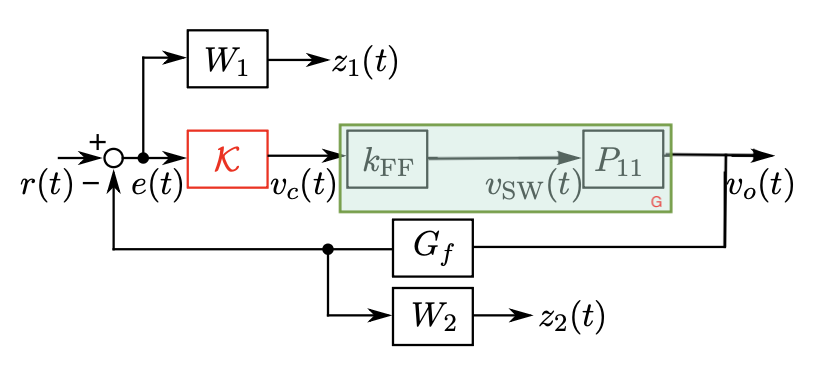

fprintf('--- SEZIONE 8: Generalized plant manuale con connect (confronto con augw) ---\n');

--- SEZIONE 8: Generalized plant manuale con connect (confronto con augw) ---



% --- Guadagno di retroazione Gf ---
Gf_val = 1;

% --- Assegnazione nomi di segnale ai blocchi esistenti ---
G_named = G;                          % G(s) = k_FF*P11(s), gia' definita in Sez. 6
G_named.InputName  = 'vc';
G_named.OutputName = 'vo';

Gf_blk = tf(Gf_val);
Gf_blk.InputName  = 'vo';
Gf_blk.OutputName = 'yf';

W1_named = W1_real;
W1_named.InputName  = 'e';
W1_named.OutputName = 'z1';

W2_named = W2_real;
W2_named.InputName  = 'vo';
W2_named.OutputName = 'z2';

% --- Nodo di somma: e(t) = r(t) - yf(t)   ---
Sum_e = sumblk('e = r - yf');


### Generazione automatica della matrice P con connect

% --- Interconnessione automatica ---
% Ingressi esogeni della pianta generalizzata: r (riferimento), vc (controllo)
% Uscite: z1, z2 (segnali pesati), e (misura data al controllore)
P_gen_connect = connect(G_named, Gf_blk, W1_named, W2_named, Sum_e, ...
    {'r','vc'}, {'z1','z2','e'});
P_gen_connect_mr = minreal(P_gen_connect, [], false);
fprintf('  Generalized plant costruita con connect: %d input, %d output\n', ...
    size(P_gen_connect,2), size(P_gen_connect,1));

  Generalized plant costruita con connect: 2 input, 3 output


%Visualizzazione di P_gen_connect_mr
P_gen_connect_mr


P_gen_connect_mr =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1       -3581  -3.008e+04           0           0           0           0
   x2   1.638e+04           0           0           0           0           0
   x3  -2.693e+04  -5.739e+07  -4.147e+06      -508.9           0           0
   x4           0           0         512           0           0           0
   x5   8.616e+05   1.837e+09           0           0  -3.142e+08  -1.838e+08
   x6           0           0           0           0   1.342e+08           0
 
  B = 
               r         vc
   x1          0       1024
   x2          0          0
   x3  6.554e+04          0
   x4          0          0
   x5          0          0
   x6          0          0
 
  C = 
               x1          x2          x3          x4          x5          x6
   z1     -0.1027      -218.9  -2.397e-07   8.898e+04           0           0
   z2        6420   1.368e+07           0           0  

### Realizzazioni individuali di P_MANUAL

% --- Realizzazioni minime individuali (una sola volta ciascuna) ---
Gss  = ss(minreal(G, 1e-6));
W1ss = ss(minreal(W1_real, 1e-6));
W2ss = ss(minreal(W2_real, 1e-6));

[Ag,Bg,Cg,Dg]     = ssdata(Gss);
[Aw1,Bw1,Cw1,Dw1] = ssdata(W1ss);
[Aw2,Bw2,Cw2,Dw2] = ssdata(W2ss);

nG  = size(Ag,1);
nW1 = size(Aw1,1);
nW2 = size(Aw2,1);
Gfv = Gf_val;   % scalare

% --- Blocco A: G libero, W1 e W2 accoppiati a G tramite le sostituzioni ---
A = [ Ag,                       zeros(nG,nW1),   zeros(nG,nW2);
    -Bw1*Gfv*Cg,               Aw1,             zeros(nW1,nW2);
    Bw2*Cg,                   zeros(nW2,nW1),  Aw2 ];

% --- Blocco B: ingressi [r, vc] ---
B = [ zeros(nG,1),              Bg;
    Bw1,                     -Bw1*Gfv*Dg;
    zeros(nW2,1),             Bw2*Dg ];

% --- Blocco C: uscite [z1, z2, e] ---
C_ind = [ -Dw1*Gfv*Cg,   Cw1,            zeros(1,nW2);
    Dw2*Cg,       zeros(1,nW1),   Cw2;
    -Gfv*Cg,       zeros(1,nW1),   zeros(1,nW2) ];

% --- Blocco D ---
D = [ Dw1,    -Dw1*Gfv*Dg;
    0,       Dw2*Dg;
    1,      -Gfv*Dg ];

P_manual_ss = ss(A,B,C_ind,D);
P_manual_ss.InputName  = {'r','vc'};
P_manual_ss.OutputName = {'z1','z2','e'};

fprintf('order(P_manual_ss) = %d\n', order(P_manual_ss));   

order(P_manual_ss) = 6



%% =========================================================
% 3. Confronto elemento per elemento
% ==========================================================

fprintf('\n--- Confronto elementi di P ---\n');


--- Confronto elementi di P ---



for i = 1:size(P_manual_ss,1)
    for j = 1:size(P_manual_ss,2)

        err_ij = norm(P_manual_ss(i,j) - ...
            P_gen_connect_mr(i,j), inf);

        fprintf('Elemento (%d,%d): %.4e\n', ...
            i,j,err_ij);
    end
end

Elemento (1,1): 1.6575e-09
Elemento (1,2): 1.6453e-07
Elemento (2,1): 0.0000e+00
Elemento (2,2): 7.0105e-10
Elemento (3,1): 0.0000e+00
Elemento (3,2): 4.1336e-13



%% =========================================================
% 4. Isolamento della cella (z1, vc)
% ==========================================================

fprintf('\n--- Isolamento della cella (z1, vc) ---\n');


--- Isolamento della cella (z1, vc) ---



entry_manual  = P_manual_ss(1,2);
entry_connect = P_gen_connect_mr(1,2);

fprintf('Ordine P_manual(1,2)  = %d\n', ...
    order(entry_manual));

Ordine P_manual(1,2)  = 6



fprintf('Ordine P_connect(1,2) = %d\n', ...
    order(entry_connect));

Ordine P_connect(1,2) = 6



diff_entry = norm(entry_manual-entry_connect,inf);

fprintf('||P_manual(1,2)-P_connect(1,2)||_inf = %.4e\n', ...
    diff_entry);

||P_manual(1,2)-P_connect(1,2)||_inf = 1.6453e-07



%% =========================================================
% 5. DC gain
% ==========================================================

fprintf('\nGuadagno DC:\n');


Guadagno DC:



fprintf('P_manual(1,2)  = %.10g\n', ...
    dcgain(entry_manual));

P_manual(1,2)  = -341545167.4



fprintf('P_connect(1,2) = %.10g\n', ...
    dcgain(entry_connect));

P_connect(1,2) = -341545167.4



%% =========================================================
% 6. High-frequency check
% ==========================================================

w_test = 1e9;

fprintf('\nGuadagno a %.2e rad/s:\n',w_test);


Guadagno a 1.00e+09 rad/s:



fprintf('|P_manual(1,2)|  = %.6e\n', ...
    abs(freqresp(entry_manual,w_test)));

|P_manual(1,2)|  = 1.052400e-07



fprintf('|P_connect(1,2)| = %.6e\n', ...
    abs(freqresp(entry_connect,w_test)));

|P_connect(1,2)| = 1.052400e-07



%% =========================================================
% 7. ZPK
% ==========================================================

fprintf('\nZPK P_manual(1,2):\n');


ZPK P_manual(1,2):


zpk(entry_manual)


ans =
 
  From input "vc" to output "z1":
  -105.18 (s+3.492e07) (s^2 + 4.147e06s + 1.194e13)
  -------------------------------------------------
  (s+4.147e06) (s+0.06283) (s^2 + 3581s + 4.929e08)
 
Continuous-time zero/pole/gain model.



fprintf('\nZPK P_connect(1,2):\n');


ZPK P_connect(1,2):


zpk(entry_connect)


ans =
 
  From input "vc" to output "z1":
  -105.18 (s+3.492e07) (s^2 + 4.147e06s + 1.194e13)
  -------------------------------------------------
  (s+4.147e06) (s+0.06283) (s^2 + 3581s + 4.929e08)
 
Continuous-time zero/pole/gain model.


### SINTESI DEL CONTROLLORE K :

% --- Sintesi H-infinity sulla pianta costruita a mano ---
[K_connect, CL_connect, gamma_connect] = hinfsyn(P_manual_ss, 1, 1);
%l'ordine del controllore varia a seconda che provenga da pesi con
%makeweight o da pesi del secondo ordine analitici
order(K_connect)

ans = 6


%Funzione del controllore per individuare numeratore e denominatore
fprintf('Funzione di trasferimento del controllore: \n');

Funzione di trasferimento del controllore: 


zpk(K_connect)


ans =
 
         3.4719e11 (s+1.571e08)^2 (s+4.458e06) (s^2 + 3581s + 4.929e08)
  ----------------------------------------------------------------------------
  (s+3.091e10) (s+8.903e07) (s+3.493e07) (s+4.147e06) (s+1.622e06) (s+0.06283)
 
Continuous-time zero/pole/gain model.


%Funzione della pianta per visualizzare numeratore e denominatore
fprintf('Funzione di trasferimento della pianta : \n')

Funzione di trasferimento della pianta : 


zpk(G)


ans =
 
    420.71 (s+3.492e07)
  ------------------------
  (s^2 + 3581s + 4.929e08)
 
Continuous-time zero/pole/gain model.




% Stampa di gamma.
fprintf('gamma* (connect)  = %.6f\n', gamma_connect);

gamma* (connect)  = 0.866309


%Stampa della norma infinitio di TZW.
Tzw_mio = lft(P_manual_ss,K_connect);
normtzw_mio = norm(Tzw_mio, 'inf');
fprintf('||Tzw||∞ = %.6f\n', normtzw_mio);

||Tzw||∞ = 0.866306



%Step response :
CL_check = feedback(G1*K_connect, 1);
%Funzione di CL
fprintf('CL : \n');

CL : 


zpk(CL_check)


ans =
 
                1.4607e14 (s+1.571e08)^2 (s+3.492e07) (s+4.458e06) (s^2 + 3581s + 4.929e08)
  --------------------------------------------------------------------------------------------------------
  (s+3.091e10) (s+8.903e07) (s+3.493e07) (s+4.181e06) (s^2 + 3581s + 4.929e08) (s^2 + 1.59e06s + 1.396e12)
 
Continuous-time zero/pole/gain model.


fprintf('Poli di CL: \n')

Poli di CL: 


pole(CL_check)

ans = 1.0e+10 *

  -3.0905 + 0.0000i
  -0.0089 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0001 + 0.0001i
  -0.0001 - 0.0001i
  -0.0004 + 0.0000i
  -0.0035 + 0.0000i


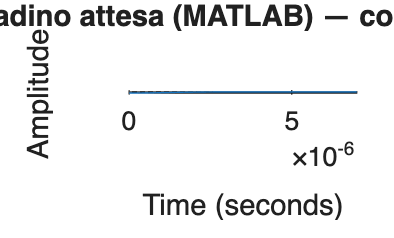

figure; step(CL_check*5);   % *5 per confrontare con l'ampiezza del tuo Step Simulink
title('Risposta al gradino attesa (MATLAB) — confronto con Simulink');

% Risposta al gradino (ampiezza 5V, griglia fine)
[y, t] = step(5 * CL_check, linspace(0, 0.0001, 10000));

% Estrai parametri con stepinfo
S = stepinfo(y, t, 'SettlingTimeThreshold', 0.02);

% --- Stampa risultati ---
fprintf('\n========== RISULTATI ==========\n');


========== RISULTATI ==========


fprintf('gamma* = %.6f\n', gamma_connect);

gamma* = 0.866309


fprintf('\nRisposta al gradino (ampiezza 5V):\n');


Risposta al gradino (ampiezza 5V):


fprintf('  Valore a regime:        %.4f V\n', mean(y(end-10:end)));

  Valore a regime:        5.0000 V


fprintf('  Sovraelongazione:       %.2f %%\n', S.Overshoot);

  Sovraelongazione:       5.71 %


fprintf('================================\n');

## Sezione 3.3 - MU-ANALYSIS

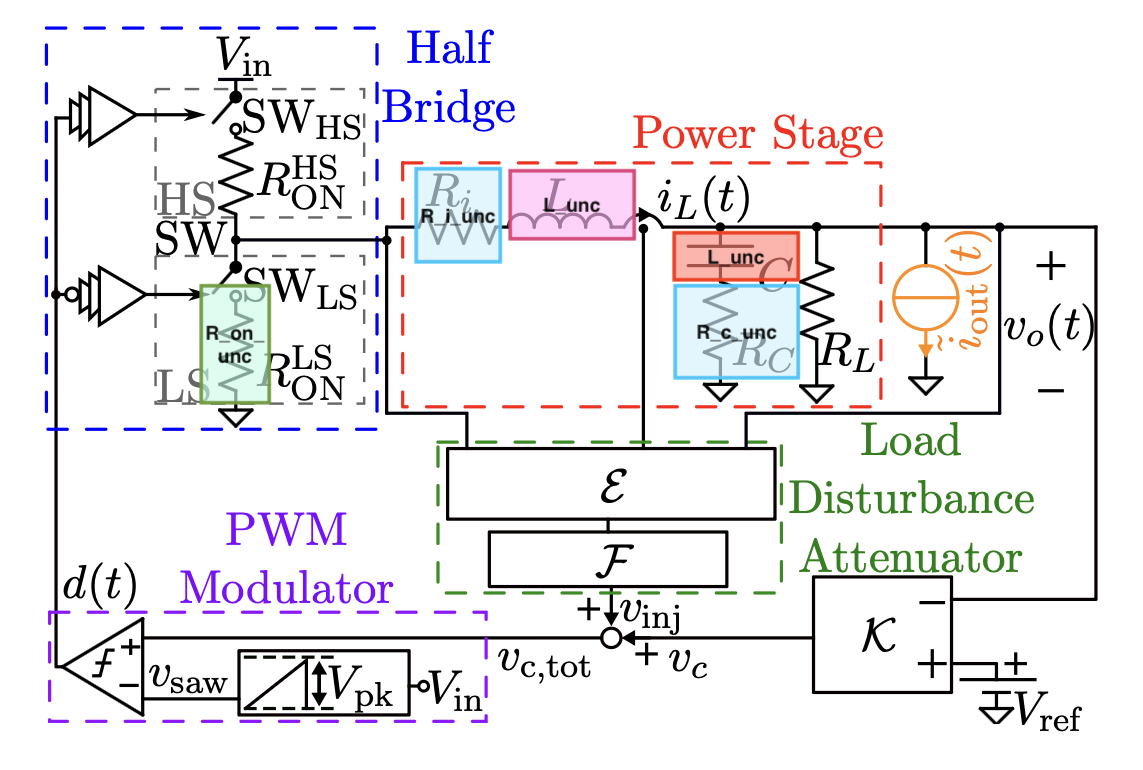

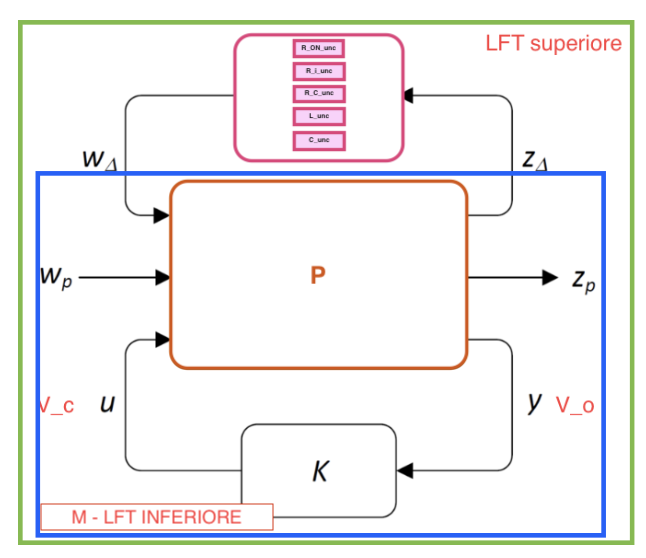

fprintf('--- SEZIONE 3.3: mu-analysis ---\n');

--- SEZIONE 3.3: mu-analysis ---


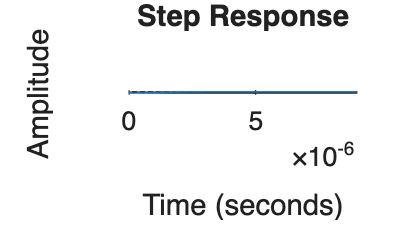


%Closed loop incerto
CL_unc = feedback(G_unc_use*K_connect, 1);
[M_nom, Delta_unc, blkstruct] = lftdata(CL_unc);

%Risposta al gradino del sistema incerto
figure;
step(5*CL_unc);



% Dimensione del canale Delta (quanti segnali collegano M a Delta)
[ny_d, nu_d] = size(Delta_unc);

% M11: SOLO il sotto-blocco quello rilevante
M11 = M_nom(1:ny_d, 1:nu_d);
normainfinito_M11 = norm(M11, 'inf');
fprintf('||M11||∞ = %.6f%\n', normainfinito_M11);

||M11||∞ = 9517084.275983

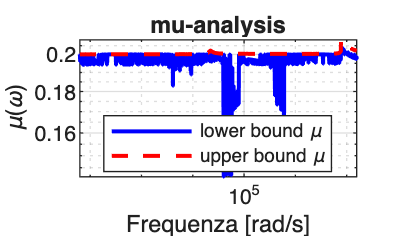

mu_lower = zeros(size(omega_vec));
mu_upper = zeros(size(omega_vec));

for kf = 1:numel(omega_vec)
    Mjw  = freqresp(M11, omega_vec(kf));
    bnds = mussv(Mjw, blkstruct);
    mu_upper(kf) = bnds(1,1);
    mu_lower(kf) = bnds(1,2);
end

figure;
loglog(omega_vec, mu_lower, 'b', omega_vec, mu_upper, 'r--', 'LineWidth', 1.5);
grid on;
legend('lower bound \mu', 'upper bound \mu', 'Location','best');
xlabel('Frequenza [rad/s]'); ylabel('\mu(\omega)');
title('mu-analysis');
xlim([omega_vec(1) omega_vec(end)]);

fprintf('max mu = %.2f',max(mu_upper));

max mu = 0.21

%% =========================================================
%  VERIFICA mediante robstab
% ==========================================================
[stabmarg, wcu, info] = robstab(CL_unc);
fprintf('  robstab margine = [%.4f, %.4f]\n', stabmarg.LowerBound, stabmarg.UpperBound);

  robstab margine = [4.8030, 4.8036]


fprintf('  mu da robstab                  = [%.4f]\n', ...
    1/stabmarg.LowerBound);

  mu da robstab                  = [0.2082]


## ROBUST PERFORMANCE 

fprintf('--- SEZIONE 3.4: Performance Robuste tramite ultidyn ---\n');

--- SEZIONE 3.4: Performance Robuste tramite ultidyn ---


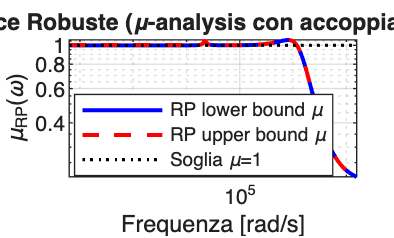


% 1. Estrai la matrice nominale M_nom_full e la blkstruct nativa di stabilità (RS)
[M_nom_full, Delta_unc, blkstruct_RS] = lftdata(CL_unc);

% 2. Calcola le dimensioni dei canali
[n_delta_y, n_delta_u] = size(Delta_unc); 
[n_total_y, n_total_u] = size(M_nom_full);

n_z = n_total_y - n_delta_y; % Uscite di performance
n_w = n_total_u - n_delta_u; % Ingressi di performance

% 3. Crea il blocco fittizio usando ultidyn
Delta_P = ultidyn('Delta_P', [n_w, n_z], 'Bound', 1);

% 4. Usa lftdata su Delta_P DA SOLO per farci dare la struct corretta da MATLAB!
[~, ~, blkstruct_P] = lftdata(Delta_P);

% Ora concateniamo le due strutture (essendo entrambe generate da lftdata, sono compatibili)
blkstruct_RP = [blkstruct_RS; blkstruct_P];

% 5. Ciclo di calcolo del mu sull'INTERA matrice M_nom_full originaria
mu_RP_lower = zeros(size(omega_vec));
mu_RP_upper = zeros(size(omega_vec));

for kf = 1:numel(omega_vec)
    % Valutiamo l'INTERA matrice nominale (quella che mappa sia Delta che Performance)
    Mjw_full = freqresp(M_nom_full, omega_vec(kf));
    
    % Ora le dimensioni di Mjw_full e blkstruct_RP coincidono perfettamente!
    bnds_RP = mussv(Mjw_full, blkstruct_RP);
    
    mu_RP_upper(kf) = bnds_RP(1,1);
    mu_RP_lower(kf) = bnds_RP(1,2);
end

% 6. Plot dei risultati
figure;
loglog(omega_vec, mu_RP_lower, 'b', omega_vec, mu_RP_upper, 'r--', 'LineWidth', 1.5);
hold on; loglog(omega_vec, ones(size(omega_vec)), 'k:', 'LineWidth', 1.2); grid on;
legend('RP lower bound \mu', 'RP upper bound \mu', 'Soglia \mu=1', 'Location','best');
xlabel('Frequenza [rad/s]'); ylabel('\mu_{RP}(\omega)');
title('Performance Robuste (\mu-analysis con accoppiamento struct)');
xlim([omega_vec(1) omega_vec(end)]);


max_mu_RP = max(mu_RP_upper);
fprintf('  max mu (Performance Robuste) = %.2f\n', max_mu_RP);

  max mu (Performance Robuste) = 1.07


### SEZIONE 4 CON INTRODUZIONE DEI 2 CONFRONTI : DOB E LEC :

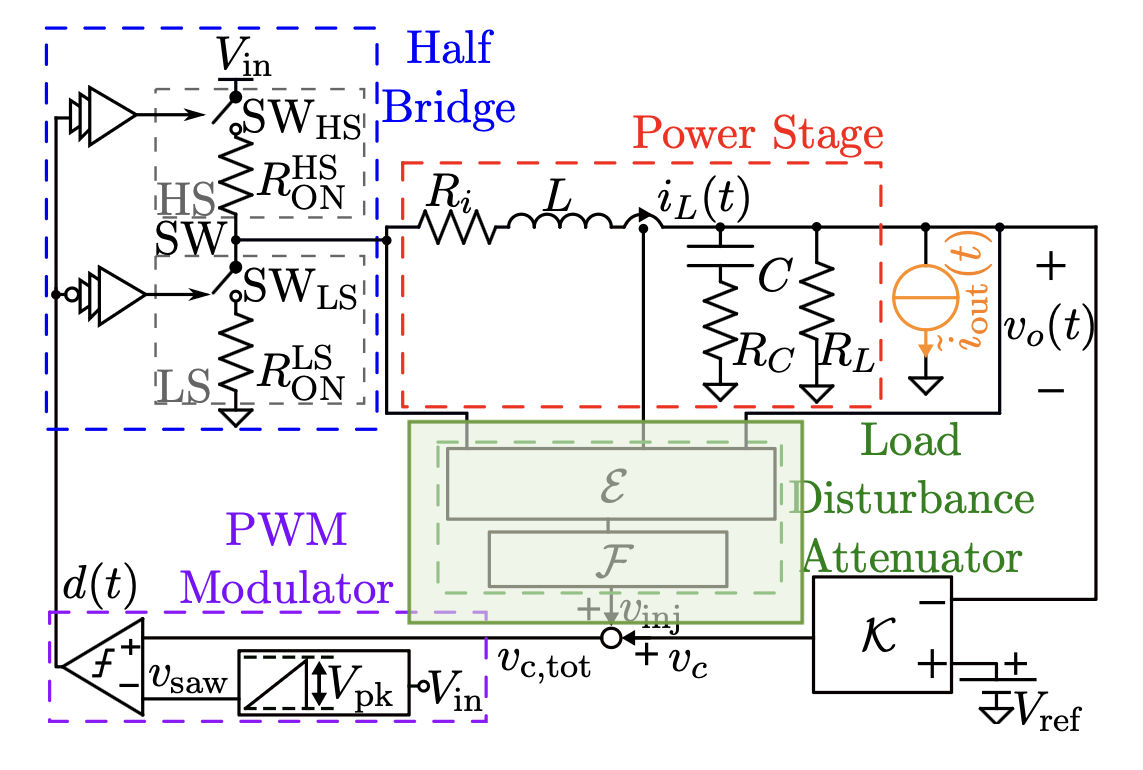


%% ===================================================================
%  Disturbance Rejection Schemes: DOB, LEC
% ===================================================================

s = tf('s');

fprintf('=================================================================\n');

fprintf(' SEZIONE 4: Schemi di Disturbance Rejection (DOB, LEC)\n');

 SEZIONE 4: Schemi di Disturbance Rejection (DOB, LEC)


fprintf('=================================================================\n\n');


%% -------------------------------------------------------------------
%  — Disturbance Observer (DOB) 
%  -------------------------------------------------------------------
fprintf('--- Disturbance Observer (DOB) ---\n');

--- Disturbance Observer (DOB) ---



% Polo di alta frequenza del filtro Q(s)
p_H = 1e6;

% --- Q(s): filtro proprio realizzabile, ordine = grado relativo di P11 (=1) ---
Q_dob = p_H / (s + p_H);

% --- omega_ESR: riuso z_ESR gia' calcolato in Sez. 2.1
omega_ESR = abs(z_ESR);   % = 1/(C*R_c)

% --- G_DOB(s): approssimazione di P11^-1*Q con zeri reali coincidenti in
%     omega_PS al posto degli zeri complessi coniugati 
G_DOB = (1 + s/omega_PS)^2 / ((1 + s/omega_ESR) * (1 + s/p_H));

fprintf('  p_H      = %.2e rad/s\n', p_H);

  p_H      = 1.00e+06 rad/s


fprintf('  omega_ESR= %.4e rad/s\n', omega_ESR);

  omega_ESR= 3.4922e+07 rad/s


fprintf('  omega_PS = %.4e rad/s (zeri coincidenti di G_DOB)\n', omega_PS);

  omega_PS = 2.2201e+04 rad/s (zeri coincidenti di G_DOB)


fprintf('  isstable(G_DOB) = %d, isproper(G_DOB) = %d\n', ...
    isstable(G_DOB), isproper(G_DOB));

  isstable(G_DOB) = 1, isproper(G_DOB) = 1



% --- Estimator E_DOB(s): 2 ingressi [vo; vSW], 1 uscita delta_hat ---
%     delta_hat = G_DOB(s)*vo - Q(s)*vSW                         
E_DOB = [G_DOB, -Q_dob];
E_DOB.InputName  = {'vo','vSW'};
E_DOB.OutputName = {'delta_hat'};

% --- Filtro di compensazione F_DOB: guadagno puro  ---
F_DOB = tf(-1/k_FF, 1);
F_DOB.InputName  = 'delta_hat';
F_DOB.OutputName = 'vinj_dob';

fprintf('  F_DOB = -1/k_FF = %.4f\n\n', -1/k_FF);

  F_DOB = -1/k_FF = -0.0333




%% -------------------------------------------------------------------
%   — Load Estimator-Compensator (LEC)  
%  -------------------------------------------------------------------
fprintf('--- SEZIONE 4.3: Load Estimator-Compensator (LEC) ---\n');

--- SEZIONE 4.3: Load Estimator-Compensator (LEC) ---



% --- Result 4: G1(s) = P21/P11, forma chiusa ---
G1_num = minreal(P21/P11, 1e-8);
G1_closed = (C*(R_L+R_c)*s + 1) / (R_L*(1 + C*R_c*s));

fprintf('  Verifica Result 4 (G1 = P21/P11 vs forma chiusa Eq.53):\n');

  Verifica Result 4 (G1 = P21/P11 vs forma chiusa Eq.53):


diff_G1 = norm(minreal(G1_num - G1_closed, 1e-8), inf);
fprintf('  ||G1_num - G1_closed||_inf = %.4e (atteso ~0)\n\n', diff_G1);

  ||G1_num - G1_closed||_inf = 1.8105e-12 (atteso ~0)




G1 = minreal(G1_closed, 1e-8);   % uso la forma chiusa, piu' pulita numericamente

% --- Result 3: verifica che Delta_P = P22*P11 - P21*P12 = P11 ---
DeltaP = minreal(P22*P11 - P21*P12, 1e-8);
diff_DeltaP = norm(minreal(DeltaP - P11, 1e-8), inf);
fprintf('  Verifica Result 3 (Delta_P = P11):\n');

  Verifica Result 3 (Delta_P = P11):


fprintf('  ||Delta_P - P11||_inf = %.4e (atteso ~0)\n\n', diff_DeltaP);

  ||Delta_P - P11||_inf = 5.6556e-11 (atteso ~0)




% --- Estimator E_LEC(s): 2 ingressi [vo; iL], 1 uscita ihat_out ---
%     ihat_out = -G1(s)*vo + iL                                   (Eq. 54)
E_LEC = [-G1, tf(1,1)];
E_LEC.InputName  = {'vo','iL'};
E_LEC.OutputName = {'iout_hat_lec'};

fprintf('  E_LEC: ordine %d, isstable = %d, isproper = %d\n\n', ...
    order(E_LEC), isstable(E_LEC), isproper(E_LEC));

  E_LEC: ordine 1, isstable = 1, isproper = 1




%% -------------------------------------------------------------------
%  SEZIONE 4.4 — Filtro di compensazione F 
%  -------------------------------------------------------------------
fprintf('--- SEZIONE 4.4: Filtro di compensazione F ---\n');

--- SEZIONE 4.4: Filtro di compensazione F ---



% --- Result 5: G2(s) = P12/P11, forma chiusa Eq. (56) ---
G2_num = minreal(P12/P11, 1e-8);
G2_closed = -s*L - R_i_prime;   % = -sL - Ri - R_ON^{HS,LS}

fprintf('  Verifica Result 5 (G2 = P12/P11 vs forma chiusa Eq.56):\n');

  Verifica Result 5 (G2 = P12/P11 vs forma chiusa Eq.56):


diff_G2 = norm(minreal(G2_num - G2_closed, 1e-8), inf);
fprintf('  ||G2_num - G2_closed||_inf = %.4e (atteso ~0)\n\n', diff_G2);

  ||G2_num - G2_closed||_inf = 4.6838e-17 (atteso ~0)




G2 = minreal(G2_closed, 1e-8);

% --- Filtro F(s) = -G2/(kFF*(1+s/pH)), regolarizzato con lo stesso
%     polo cheap p_H usato per il DOB e per il pole placement UIO  ---
F_filter = minreal(-G2 / (k_FF * (1 + s/p_H)), 1e-8);

fprintf('  F(s) = (sL+Ri_prime) / (k_FF*(1+s/p_H))\n');

  F(s) = (sL+Ri_prime) / (k_FF*(1+s/p_H))


fprintf('  isstable(F) = %d, isproper(F) = %d\n', isstable(F_filter), isproper(F_filter));

  isstable(F) = 1, isproper(F) = 1


fprintf('  DC gain F(0) = R_i_prime/k_FF = %.6e\n\n', dcgain(F_filter));

  DC gain F(0) = R_i_prime/k_FF = 4.500000e-04



%% ===================================================================
%  SEZIONE 5 — LEC Stability Analysis
% ===================================================================

fprintf('=================================================================\n');

fprintf(' SEZIONE 5: LEC Stability Analysis\n');

 SEZIONE 5: LEC Stability Analysis


fprintf('=================================================================\n\n');


fprintf('--- SEZIONE 5.1: Nominal stability and performance (Theorem 1) ---\n');

--- SEZIONE 5.1: Nominal stability and performance (Theorem 1) ---



s = tf('s');
Pss = [P11, P12; P21, P22];
% --- Costruzione anello interno ---
Pss.InputName  = {'vSW','iout_tilde'};
Pss.OutputName = {'vo','iL'};

E_LEC.InputName  = {'vo','iL'};
E_LEC.OutputName = {'iout_hat_lec'};

F_filter.InputName  = 'iout_hat_lec';
F_filter.OutputName = 'vinj';

Sum_pre = sumblk('u_sum = vc + vinj');

kFF_blk = tf(k_FF,1);
kFF_blk.InputName  = 'u_sum';
kFF_blk.OutputName = 'vSW';

% Inner loop: inputs [vc, iout_tilde], outputs [vo, iL]  (Eq. 58)
CL_LEC = connect(Pss, E_LEC, F_filter, kFF_blk, Sum_pre,...
    {'vc','iout_tilde'}, {'vo','iL'});
CL_LEC = minreal(CL_LEC, 1e-6);

3 states removed.



fprintf('  order(CL_LEC) = %d\n', order(CL_LEC));

  order(CL_LEC) = 3


fprintf('  isstable(CL_LEC) = %d (expected 1, consistent with Theorem 1)\n\n', ...
    isstable(CL_LEC));

  isstable(CL_LEC) = 1 (expected 1, consistent with Theorem 1)




% --- Verification 1: vc -> vo must remain EXACTLY G = kFF*P11 (Eq. 59) ---
% Use minreal only if the model is proper
CL_LEC_vc_to_vo = CL_LEC(1,1);
if isproper(CL_LEC_vc_to_vo)
    CL_LEC_vc_to_vo = minreal(CL_LEC_vc_to_vo, 1e-6);
end

1 state removed.


G_check = G;
if isproper(G_check)
    G_check = minreal(G_check, 1e-6);
end

err_vc_vo = norm(CL_LEC_vc_to_vo - G_check, inf);
fprintf('  Verification: vc->vo preserved (expected ~0):\n');

  Verification: vc->vo preserved (expected ~0):


fprintf('  ||CL_LEC(vc->vo) - G||_inf = %.4e\n\n', err_vc_vo);

  ||CL_LEC(vc->vo) - G||_inf = 9.5081e-09




% --- Verification 2: iout_tilde -> vo must become P12*s/(s+pH) (Eq. 59) ---
G_iout_to_vo_expected = P12 * s/(s+p_H);
CL_LEC_iout_to_vo = CL_LEC(1,2);
% Il vero canale iout_tilde->vo, CON l'anello esterno di K chiuso


% Use minreal only if the model is proper
if isproper(CL_LEC_iout_to_vo)
    CL_LEC_iout_to_vo = minreal(CL_LEC_iout_to_vo, 1e-6);
end
if isproper(G_iout_to_vo_expected)
    G_iout_to_vo_expected = minreal(G_iout_to_vo_expected, 1e-6);
end

err_iout_vo = norm(CL_LEC_iout_to_vo - G_iout_to_vo_expected, inf);
fprintf('  Verification: iout->vo = P12*s/(s+pH) (expected ~0):\n');

  Verification: iout->vo = P12*s/(s+pH) (expected ~0):


fprintf('  ||CL_LEC(iout->vo) - P12*s/(s+pH)||_inf = %.4e\n\n', err_iout_vo);

  ||CL_LEC(iout->vo) - P12*s/(s+pH)||_inf = 1.7930e-12




if err_vc_vo > 1e-3 || err_iout_vo > 1e-3
    warning('One of the Theorem 1 verifications failed: check signs/connections.');
else
    fprintf('  ==> Theorem 1 NUMERICALLY CONFIRMED: vc->vo preserved,\n');
    fprintf('      iout->vo filtered with high-pass s/(s+pH).\n\n');
end

  ==> Theorem 1 NUMERICALLY CONFIRMED: vc->vo preserved,


      iout->vo filtered with high-pass s/(s+pH).




% --- Graphical comparison: disturbance rejection with and without LEC ---
S_nominal = feedback(1, G*K_connect);
G_iout_to_vo_full_LEC = minreal(S_nominal*CL_LEC_iout_to_vo, 1e-6);

3 states removed.


%% ===================================================================
%  SEZIONE 6.1 — Simulation results: confronto No DR / DOB / LEC
% ===================================================================

fprintf('=================================================================\n');

fprintf(' SEZIONE 6.1: Confronto simulativo No DR / DOB  / LEC ');

 SEZIONE 6.1: Confronto simulativo No DR / DOB  / LEC 

fprintf('=================================================================\n\n');


% --- Parametri fissi della simulazione (Sez. 6.1 del paper) ---
RL_sim = 5;              % [Ohm] RL FISSO per queste simulazioni (non randomizzato)
Iout_amp   = 8;           % [A]   ampiezza del gradino di disturbo
Iout_slope = 1e6;         % [A/s] slope del gradino (rampa, non ideale)
n_runs = 50;              % numero di simulazioni Monte Carlo

fprintf('  RL fisso = %.1f Ohm (coerente col paper, corrente statica 1A)\n', RL_sim);

  RL fisso = 5.0 Ohm (coerente col paper, corrente statica 1A)


fprintf('  Disturbo: ampiezza = %d A, slope = %.0e A/s, n_runs = %d\n\n', ...
    Iout_amp, Iout_slope, n_runs);

  Disturbo: ampiezza = 8 A, slope = 1e+06 A/s, n_runs = 50




% --- Vettore tempo e segnale di disturbo (rampa poi costante) ---
t_rise = Iout_amp / Iout_slope;         % tempo di salita della rampa
t_vec  = linspace(-10e-6, 140e-6, 6000)';
iout_signal = zeros(size(t_vec));
idx_rise = (t_vec >= 0) & (t_vec < t_rise);
idx_hold = (t_vec >= t_rise);
iout_signal(idx_rise) = Iout_slope * t_vec(idx_rise);
iout_signal(idx_hold) = Iout_amp;

r_signal = zeros(size(t_vec));   % nessun gradino di riferimento: guardiamo solo vo attorno a Vtarget

% --- Contenitori per i risultati Monte Carlo ---
vo_noDR = zeros(n_runs, numel(t_vec));
vo_DOB  = zeros(n_runs, numel(t_vec));
vo_LEC  = zeros(n_runs, numel(t_vec));

vc_noDR = zeros(n_runs, numel(t_vec));
vc_DOB  = zeros(n_runs, numel(t_vec));
vc_LEC  = zeros(n_runs, numel(t_vec));

n_unstable = struct('noDR',0,'UIO',0,'LEC',0);

fprintf('  Esecuzione di %d simulazioni Monte Carlo...\n', n_runs);

  Esecuzione di 50 simulazioni Monte Carlo...


for run_idx = 1:n_runs

    % --- Campionamento uniforme di L, C, Ri, RON, RC nei rispettivi range
    %     (RL resta fisso a RL_sim) ---
    Lk   = L*(1 + delta_L*(2*rand()-1));
    Ck   = C*(1 + delta_C*(2*rand()-1));
    Rik  = R_i*(1 + delta_Ri*(2*rand()-1));
    RONk = R_ON*(1 + delta_RON*(2*rand()-1));
    Rck  = R_c*(1 + delta_Rc*(2*rand()-1));

    Pss_k = build_Pss_physical(Lk, Ck, Rik, RONk, Rck, RL_sim);

    % --- Costruzione dei quattro anelli chiusi (E/F FISSI, nominali;
    %     solo Pss_k varia da run a run — e' il punto della Sez. 5.2) ---
    CL_noDR_k = build_CL_DR(Pss_k, K_connect, k_FF, [], []);
    CL_DOB_k  = build_CL_DR(Pss_k, K_connect, k_FF, E_DOB, F_DOB);
    CL_LEC_k  = build_CL_DR(Pss_k, K_connect, k_FF, E_LEC, F_filter);

    % --- Simulazione temporale (lsim), input [r, iout_tilde] ---
    if isstable(CL_noDR_k)
        y = lsim(CL_noDR_k, [r_signal, iout_signal], t_vec);
        vo_noDR(run_idx,:) = y(:,1)' + 5;   % + Vtarget
        vc_noDR(run_idx,:) = y(:,3)';
    else
        n_unstable.noDR = n_unstable.noDR + 1;
        vo_noDR(run_idx,:) = NaN; vc_noDR(run_idx,:) = NaN;
    end

    if isstable(CL_DOB_k)
        y = lsim(CL_DOB_k, [r_signal, iout_signal], t_vec);
        vo_DOB(run_idx,:) = y(:,1)' + 5;
        vc_DOB(run_idx,:) = y(:,3)';
    else
        n_unstable.DOB = n_unstable.DOB + 1;
        vo_DOB(run_idx,:) = NaN; vc_DOB(run_idx,:) = NaN;
    end

    if isstable(CL_LEC_k)
        y = lsim(CL_LEC_k, [r_signal, iout_signal], t_vec);
        vo_LEC(run_idx,:) = y(:,1)' + 5;
        vc_LEC(run_idx,:) = y(:,3)';
    else
        n_unstable.LEC = n_unstable.LEC + 1;
        vo_LEC(run_idx,:) = NaN; vc_LEC(run_idx,:) = NaN;
    end

    if mod(run_idx,10)==0
        fprintf('    run %d/%d completato\n', run_idx, n_runs);
    end
end

    run 10/50 completato
    run 20/50 completato
    run 30/50 completato
    run 40/50 completato
    run 50/50 completato


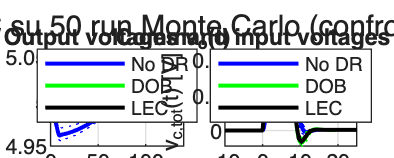


%% -------------------------------------------------------------------
%  Statistiche (media + inviluppo min/max) e grafici, stile Fig. 9
%  -------------------------------------------------------------------
vo_noDR_mean = mean(vo_noDR,1,'omitnan'); vo_noDR_min = min(vo_noDR,[],1,'omitnan'); vo_noDR_max = max(vo_noDR,[],1,'omitnan');
vo_DOB_mean  = mean(vo_DOB,1,'omitnan');  vo_DOB_min  = min(vo_DOB,[],1,'omitnan');  vo_DOB_max  = max(vo_DOB,[],1,'omitnan');
vo_LEC_mean  = mean(vo_LEC,1,'omitnan');  vo_LEC_min  = min(vo_LEC,[],1,'omitnan');  vo_LEC_max  = max(vo_LEC,[],1,'omitnan');

vc_noDR_mean = mean(vc_noDR,1,'omitnan'); vc_noDR_min = min(vc_noDR,[],1,'omitnan'); vc_noDR_max = max(vc_noDR,[],1,'omitnan');
vc_DOB_mean  = mean(vc_DOB,1,'omitnan');  vc_DOB_min  = min(vc_DOB,[],1,'omitnan');  vc_DOB_max  = max(vc_DOB,[],1,'omitnan');
vc_LEC_mean  = mean(vc_LEC,1,'omitnan');  vc_LEC_min  = min(vc_LEC,[],1,'omitnan');  vc_LEC_max  = max(vc_LEC,[],1,'omitnan');

t_us = t_vec * 1e6;   % tempo in microsecondi, come Fig. 9

figure('Position',[100 100 1200 480]);

% --- Subplot (a): v_o(t) ---
subplot(1,2,1);
plot(t_us, vo_noDR_mean, 'b', 'LineWidth', 1.5); hold on;
plot(t_us, vo_noDR_min, 'b:', t_us, vo_noDR_max, 'b:');
plot(t_us, vo_DOB_mean, 'g', 'LineWidth', 1.5);
plot(t_us, vo_DOB_min, 'g:', t_us, vo_DOB_max, 'g:');
plot(t_us, vo_LEC_mean, 'k', 'LineWidth', 1.5);
plot(t_us, vo_LEC_min, 'k:', t_us, vo_LEC_max, 'k:');
grid on; xlim([0 140]);
xlabel('time [\mus]'); ylabel('v_o(t) [V]');
title('Output voltages v_o(t)');
legend('No DR','','','DOB','','','LEC','Location','best');

% --- Subplot (b): v_c,tot(t) ---
subplot(1,2,2);
plot(t_us, vc_noDR_mean, 'b', 'LineWidth', 1.5); hold on;
plot(t_us, vc_noDR_min, 'b:', t_us, vc_noDR_max, 'b:');
plot(t_us, vc_DOB_mean, 'g', 'LineWidth', 1.5);
plot(t_us, vc_DOB_min, 'g:', t_us, vc_DOB_max, 'g:');
plot(t_us, vc_LEC_mean, 'k', 'LineWidth', 1.5);
plot(t_us, vc_LEC_min, 'k:', t_us, vc_LEC_max, 'k:');
grid on; xlim([-10 25]);
xlabel('time [\mus]'); ylabel('v_{c,tot}(t) [V]');
title('Command input voltages v_{c,tot}(t)');
legend('No DR','','','DOB','','','LEC','Location','best');

sgtitle('Confronto DOB/UIO/LEC su 50 run Monte Carlo (confronta con Fig. 9 del paper)');


fprintf('  Figura generata: confronto Fig.9-style su %d run\n\n', n_runs);

  Figura generata: confronto Fig.9-style su 50 run




% --- Riepilogo numerico: undershoot massimo per schema ---
fprintf('  Undershoot massimo (peggior run) rispetto a 5V:\n');

  Undershoot massimo (peggior run) rispetto a 5V:


fprintf('    No DR = %.2f mV\n', 1000*(5-min(vo_noDR(:))));

    No DR = 43.85 mV


fprintf('    DOB   = %.2f mV\n', 1000*(5-min(vo_DOB(:))));

    DOB   = 5.59 mV


fprintf('    LEC   = %.2f mV\n\n', 1000*(5-min(vo_LEC(:))));

    LEC   = 11.01 mV



## SIMULINK : SALVATAGGIO E RAPPRESENTAZIONE IN MATLAB :

## SCHEMA SEMPLIFICATO 

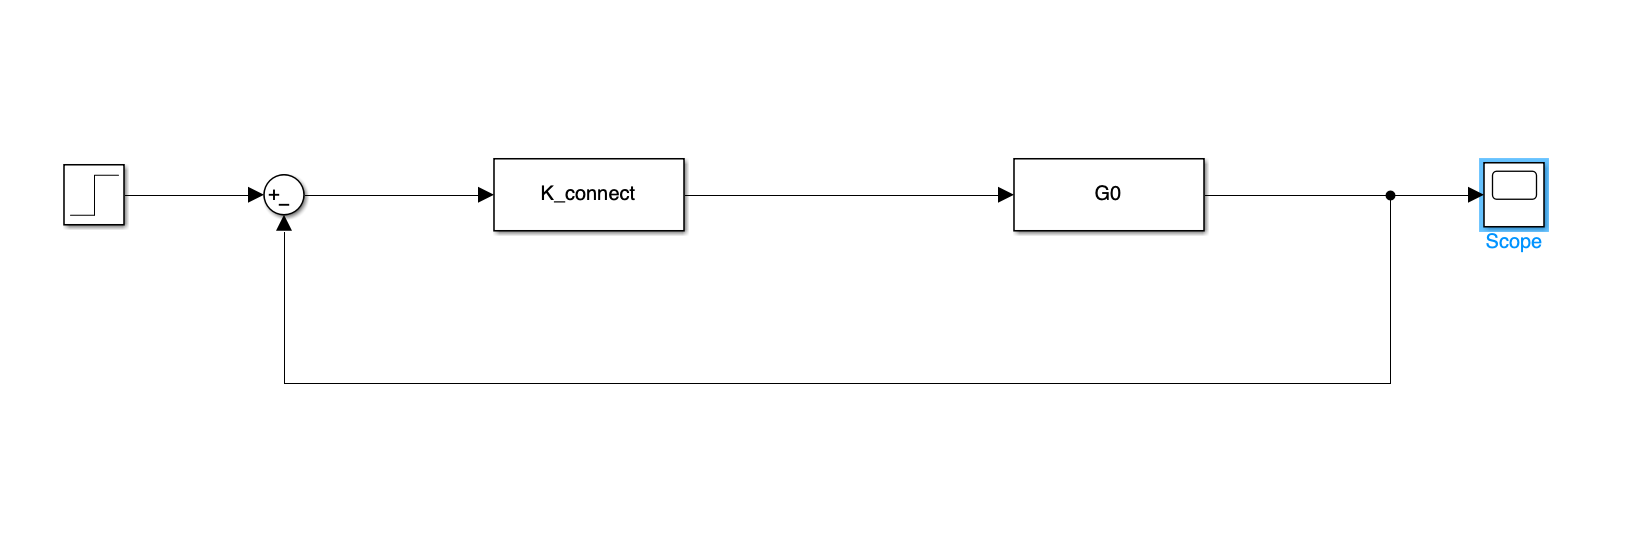

%% ===================================================================
%  SEZIONE 7 — Confronto Simulink vs MATLAB (riferimento e disturbo)
% ===================================================================

fprintf('=================================================================\n');

fprintf(' SEZIONE 7: Confronto Simulink vs MATLAB\n');

 SEZIONE 7: Confronto Simulink vs MATLAB


fprintf('=================================================================\n\n');


%% --- Ricostruzione della pianta di stato (Pss) ---
P_full = [P11, P12; P21, P22];
Pss1 = ss(minreal(P_full, 1e-8));
Pss1.InputName  = {'vSW','iout_tilde'};
Pss1.OutputName = {'vo','iL'};

%% -------------------------------------------------------------------
%  7.1 — Risposta al gradino di RIFERIMENTO (nessun disturbo)
%  -------------------------------------------------------------------
fprintf('--- 7.1: Confronto gradino di riferimento ---\n');

--- 7.1: Confronto gradino di riferimento ---


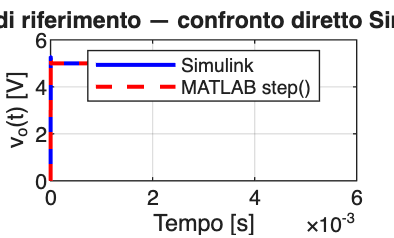


CL_check = feedback(G*K_connect, 1);

figure;
[y_matlab, t_matlab] = step(CL_check*5, 0.005);
%vosimulink = out.vosimulink;   % ora vosimulink esiste nel workspace base
plot(vosimulink.Time, vosimulink.Data, 'b', 'LineWidth', 1.5); hold on;
plot(t_matlab, y_matlab, 'r--', 'LineWidth', 1.5);
legend('Simulink', 'MATLAB step()', 'Location','best');
xlabel('Tempo [s]'); ylabel('v_o(t) [V]');
title('v_o(t) per gradino di riferimento — confronto diretto Simulink vs MATLAB');
grid on;


fprintf('  Figura generata: confronto diretto sul gradino di riferimento\n\n');

  Figura generata: confronto diretto sul gradino di riferimento



### SCHEMA COMPLESSO :

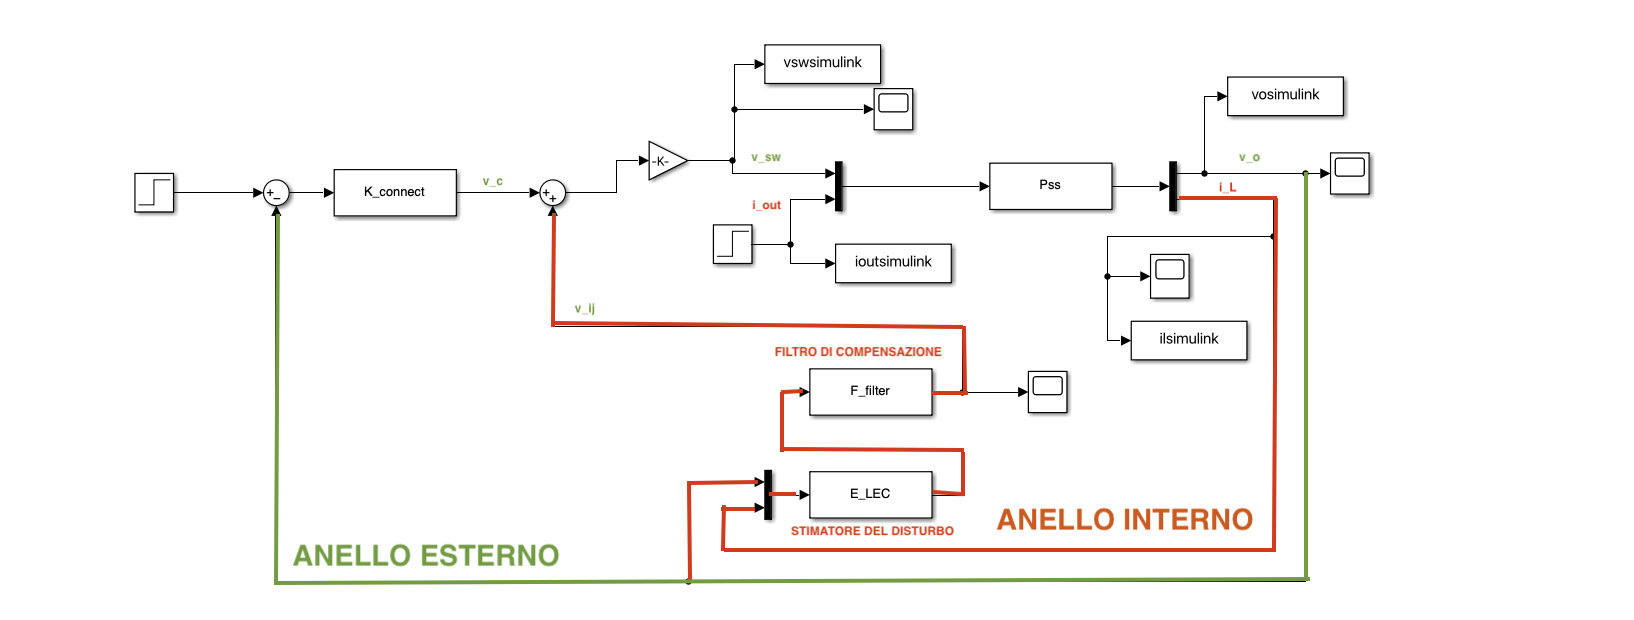

%% --- Confronto con gradini a istanti diversi (usando lsim) ---
fprintf('--- 7.3bis: Confronto con gradini sfasati nel tempo (lsim) ---\n');

--- 7.3bis: Confronto con gradini sfasati nel tempo (lsim) ---


Iout_step_amp = 0.5;

Sum_pre = sumblk('u_sum = vc + vinj');
Sum_e2  = sumblk('e = r - vo');
K_connect.InputName  = {'e'};
K_connect.OutputName = {'vc'};

Pss = [P11, P12; P21, P22];
Pss = ss(minreal(Pss, 1e-8));
Pss.InputName  = {'vSW','iout_tilde'};
Pss.OutputName = {'vo','iL'};

% Ora ricostruisci CL_full_LEC con QUESTO Pss
CL_full_LEC = connect(K_connect, kFF_blk, Pss, E_LEC, F_filter, Sum_pre, Sum_e2, ...
    {'r','iout_tilde'}, {'vo','iL'});
CL_full_LEC = minreal(CL_full_LEC, 1e-6);

3 states removed.


% *** IMPOSTA QUESTI DUE VALORI COERENTI CON I BLOCCHI STEP IN SIMULINK ***
t_step_r    = 0;       % istante del gradino di riferimento [s]
t_step_dist = 0.005;   % istante del gradino di disturbo di carico [s] (verifica sul blocco Step!)

% Vettore tempo: usa lo stesso orizzonte/campionamento di vosimulink se puoi
t_c = linspace(0, 0.02, 20000)';   % adatta il limite superiore se serve

% Costruzione dei due ingressi come gradini shiftati
r_in    = 5             * (t_c >= t_step_r);
iout_in = Iout_step_amp * (t_c >= t_step_dist);

% Simulazione diretta del sistema 2 input / 2 output (niente sovrapposizione manuale)
y_comb = lsim(CL_full_LEC, [r_in, iout_in], t_c);
y_vo_comb = y_comb(:,1);
y_iL_comb = y_comb(:,2);

figure;
plot(vosimulink1.Time, vosimulink1.Data, 'b', 'LineWidth', 1.5); hold on;

Unable to resolve the name 'vosimulink1.Time'.

legend('Simulink', 'Location','best');
xlabel('Tempo [s]'); ylabel('v_o(t) [V]');
title('v_o(t) — riferimento + disturbo (istanti reali)'); grid on;

figure;
plot(ilsimulink.Time, ilsimulink.Data, 'b', 'LineWidth', 1.5); hold on;
legend('Simulink', 'Location','best');
xlabel('Tempo [s]'); ylabel('i_L(t) [A]');
title('i_L(t) — riferimento + disturbo (istanti reali)'); grid on;

fprintf('  Figure generate con lsim e ingressi correttamente sfasati nel tempo\n\n');

